# Double-Mass-Spring-Damper System

## Problem Description

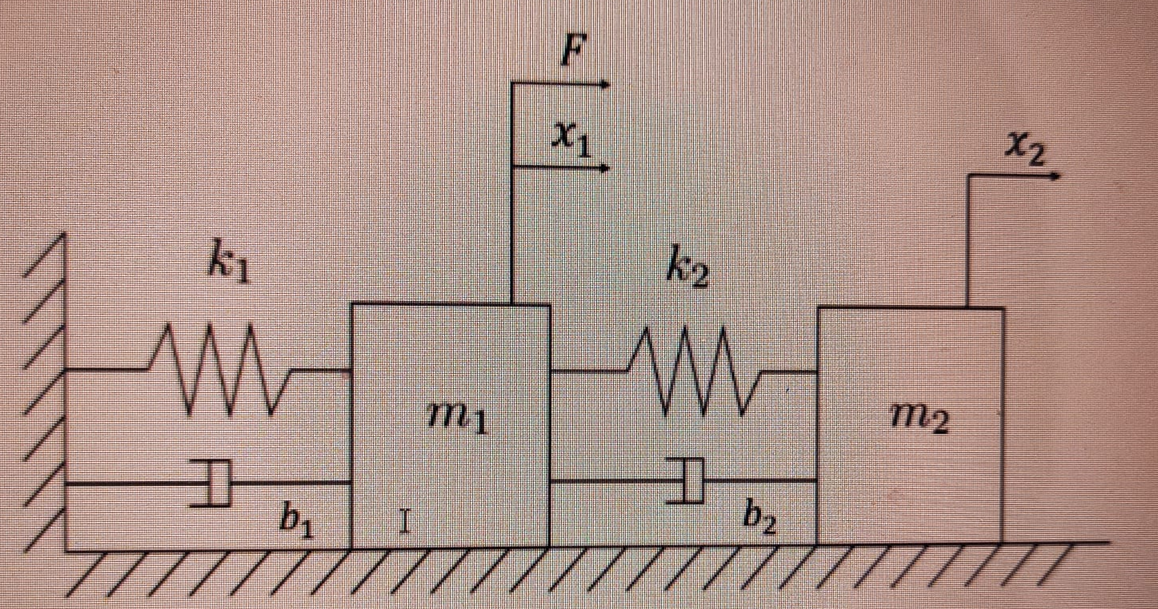

The system consists of two masses m_1 and m_2 with each having a spring and damper connecting them to a stationary wall and mass m_1 respectively. An input force F is applied on m_1 which causes both masses to oscillate due to the nature of the system.

The system will be modelled in a simscape environment.

## Variable Declaration

m_1 =1;                                % mass 1 in kg
m_2 =1;                                % mass 2 in kg
b_1 = 1;                              % damper 1 constant in N/ms^-1
k_1 = 1;                              % stiffness of spring 1 in N/m
b_2 = 1;                              % damper 2 constant in N/ms^-1
k_2 = 1;                              % stiffness of spring 2 in N/m
F_in = 1;                             % input force in N
simtime = 30;                                                 % runtime in s

## Simulation and Graph Plots

sim('Capstone_project_1.slx')

Unable to find system or file 'Capstone_project_1.slx'.

figure
plot(IN.time, IN.data)
grid on
hold on
x_1.data = reshape(x_1.data, [], 1);
x_2.data = reshape(x_2.data, [], 1);
plot(x_1.time, x_1.data)
plot(x_2.time, x_2.data)
hold off
xlabel('t/s')
ylabel({'$F_{in}$/N', '$x_{1}$/m', '$x_{2}$/m'}, 'Interpreter', 'latex')
legend({'$F_{in}$', '$x_{1}$', '$x_{2}$'}, 'Interpreter', 'latex')
title('Double-Mass-Spring-Damper Response')

figure
title('Double-Mass-Spring-Damper Response')
plot(IN.time, IN.data)
grid on
hold on
x_1_dot.data = reshape(x_1_dot.data, [], 1);
x_2_dot.data = reshape(x_2_dot.data, [], 1);
plot(x_1_dot.time, x_1_dot.data)
plot(x_2_dot.time, x_2_dot.data)
hold off
xlabel('t/s')
ylabel({'$F_{in}$/N', '$\dot{x}_1$', '$\dot{x}_2$'}, 'Interpreter', 'latex')
legend({'$F_{in}$', '$\dot{x}_1$', '$\dot{x}_2$'}, 'Interpreter', 'latex')
title('Double-Mass-Spring-Damper Response')